Joseph Ntaimo Feb 2024

# 2.12 Lab 4 Motor Modeling

### Motor Parameters

#### Fundamental parameters

Fill out the motor torque constant and Back EMF Constant based on the motor information here

Motor torque constant

t_stall = 1.47; %kgcm
stall_current = 9.2; %(A) Stall current of the motor
Kt = (t_stall*9.81/100)/stall_current %(Nm/A) motor torque constant'

Kt = 0.0157

Back EMF Constant

V = 12; %(v) Voltage of the motor
RPM = 5800;
Ke = V/(RPM/60*2*pi) %(V/(rad/s))

Ke = 0.0198

What will you use for the actual Kt estimate? Hint, you may have to tweak this later

Kt = (Kt+Ke)/2

Kt = 0.0177

Gear ratio

r = 99.5; %gear ratio

Armature resistance

R = 1.3; %(Ohms) Armature resistance

Motor Rotor inertia

r_rotor = 1/8*25.4/1000/2; %(m)radius of the rotor
l_rotor = 0.075; %(m) approx length of rotor
rho_rotor = 7.75;%(kg/m^3) density of steel rotor
v_rotor = pi*r_rotor^2*l_rotor%(m^3) volume of rotor

v_rotor = 5.9380e-07

m_rotor = v_rotor*rho_rotor; %(kg) mass of rotor
I_rotor = m_rotor*r_rotor^2 %(kgm^2)

I_rotor = 1.1598e-11

Load moment of inertia

m_motor = 0.486; %(kg) mass of the motor
r_motor = 0.036/2;%(m) radius of the motor
m_arm = 0.059; %(kg) mass of a single arm
Lhole = 0.024; %(m) distance between large holes on the arm
L1 = Lhole*7; %(m) length of first linkage
L2 = Lhole*9; %(m) length of second linkage
L = 0.216; %(m) length of full C channel

Fill in the moment of inertias for both motors

Il_2 = m_arm*(L2/2)^2 %(kgm^2) Load moment of inertia for second motor

Il_2 = 6.8818e-04

The moment of a single motor about it's axis of rotation should be useful for calculating the moment of inertia for the first motor.

Im = m_motor*r_motor^2; %(kgm^2) Motor moment of inertia
Il_1 = Im + (m_motor*L1^2 + Im) + (m_arm*L1^2 + Il_2) %(kgm^2) Load moment of inertia for first motor

Il_1 = 0.0164

- What is the ratio between the two motor inertias? $\frac{I_{\mathrm{L1}} }{I_{\mathrm{L2}} }$

- Why is this ratio so large?

- What does this ratio say about the amount of gain your motors will need to move quickly? Which motor should have notably higher gains?

Inertia_ratio = Il_1/Il_2

Inertia_ratio = 23.8096

Viscous damping

b = 0.01; %(Nm/(rad/s)) Viscous damping

#### Derived parameters

Motor constant

Km = Kt/sqrt(R) %(Nm/w^1/2)

Km = 0.0155

Effective inertia

I1 = Il_1 + r^2*I_rotor %(kgm^2)

I1 = 0.0164

I2 = Il_2 + r^2*I_rotor

I2 = 6.8818e-04

Effective damping

B = b + r^2*Km^2 %(Nm/(rad/s))

B = 0.0990

Input gain

k = r*Kt/R %(Nm/v)

k = 0.2617

Let's make the transfer function!

m1 = motorModel(I1, k, B);
m2 = motorModel(I2, k, B);

Let's take a look at the poles and zeros on the root locus. This can give us insight into how to control this system.

- Is Kp control stable?

- What happens to the closed loop natural frequency of the system as kp increases?

- What happens to damping as kp increases?

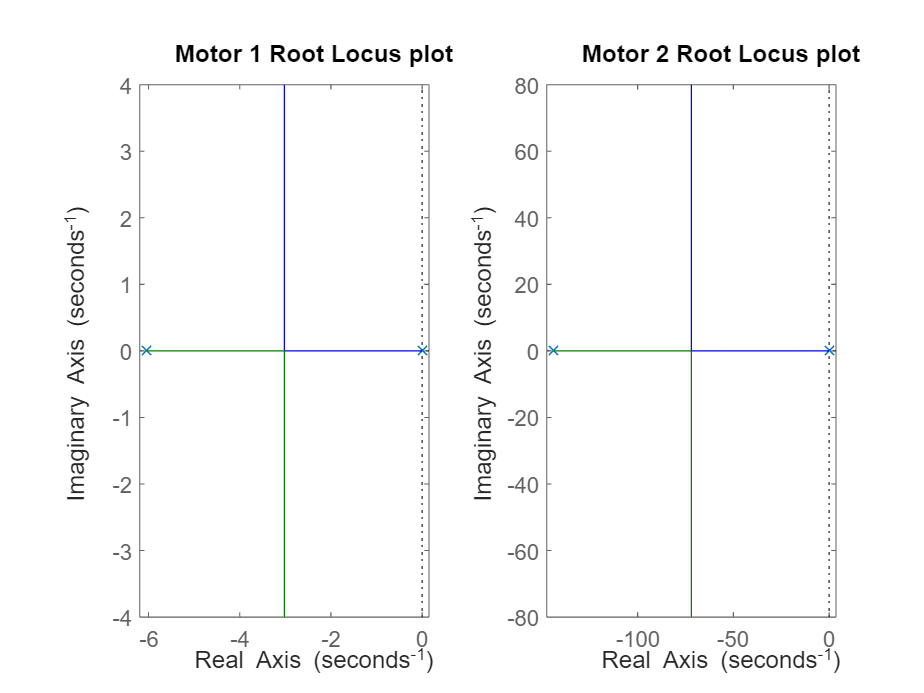

figure;
subplot(1,2,1);
rlocus(m1)
title("Motor 1 Root Locus plot");
subplot(1,2,2);
rlocus(m2);
title("Motor 2 Root Locus plot")

What about the frequency response? 

- What is your phase at the desired crossover frequency

- What phase margin does that phase correspond to?

- Do you need to gain phase or lose phase to make this system perform at your desired crossover?

- Which term in PID will help you gain phase - i.e Proportional, Integral, or Derivative?

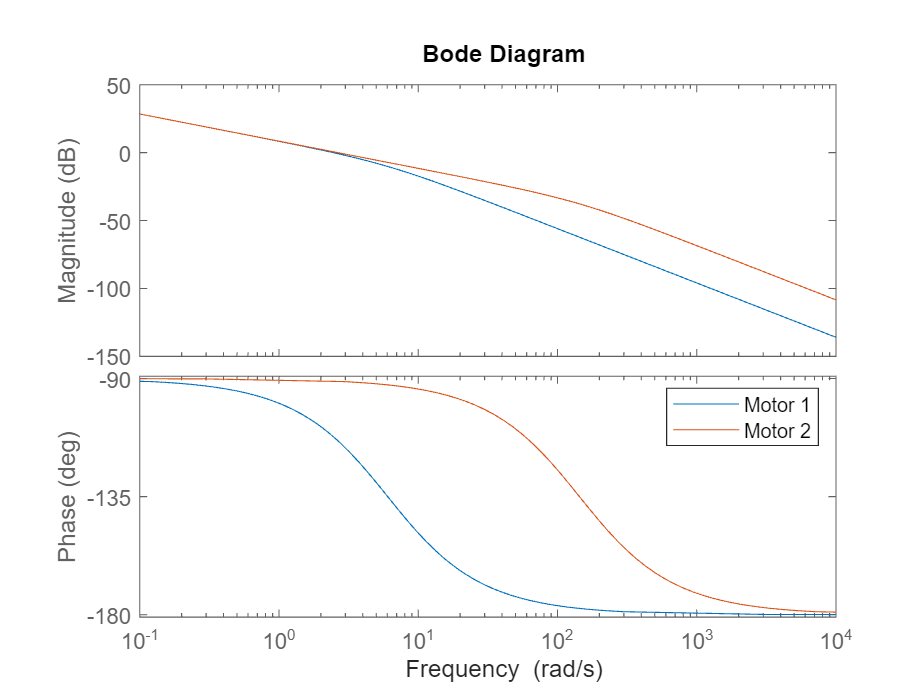

figure;
bode(m1)
hold on
bode(m2);
legend("Motor 1", "Motor 2")
hold off

### Time Responses

Let's see how fast these motors respond to an open loop step in voltage and assess if it makes sense

Since the motors will continuously rotate due to a step in voltage, reading position doesn't make much sense because it will keep increasing. 

- Instead of having position as the output of the step, what is a simple way to make the output velocity? Implement it.

- How can you make a step of 12V for the motor?

- Try switching the gear ratio to 

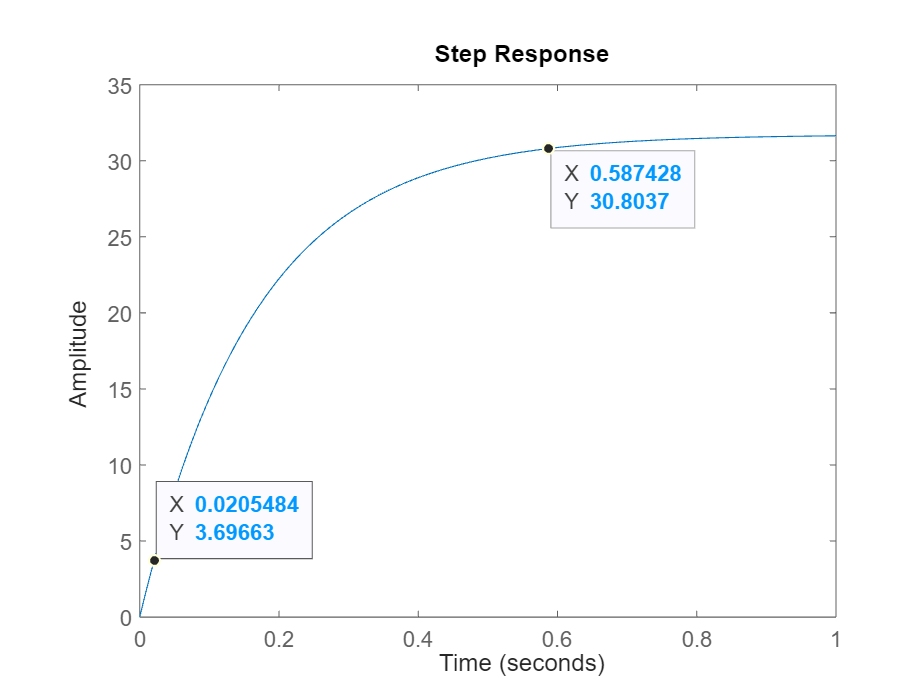

s = tf('s');
step(s*m1*V);

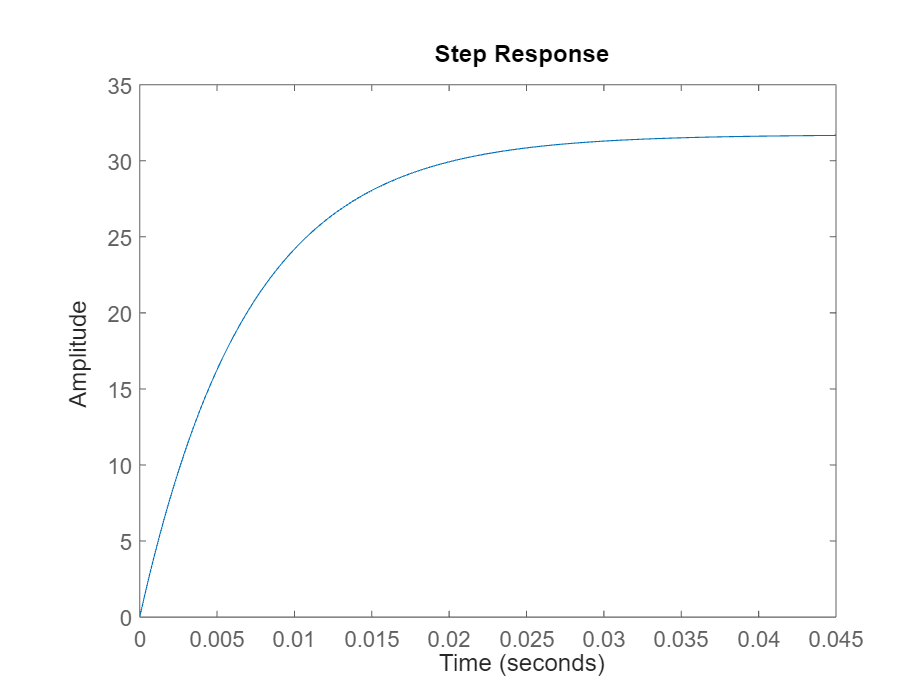

step(s*m2*V);

- Does the steady state velocity make sense for the motor given it's RPM rating? 

- How could you adjust your model to make the steady state velocity make sense? (Hint - Kt)

- What is the time constant estimate for both of the motors

Helpful equation $V_{\mathrm{RPM}} =\frac{V_{\frac{\mathrm{rad}}{s}} \cdot 60}{2\cdot \pi }$

ss_vel = 0;
tau1 = 0;
tau2 = 0;

Let's overlay the plots to compare the speeds of the motors

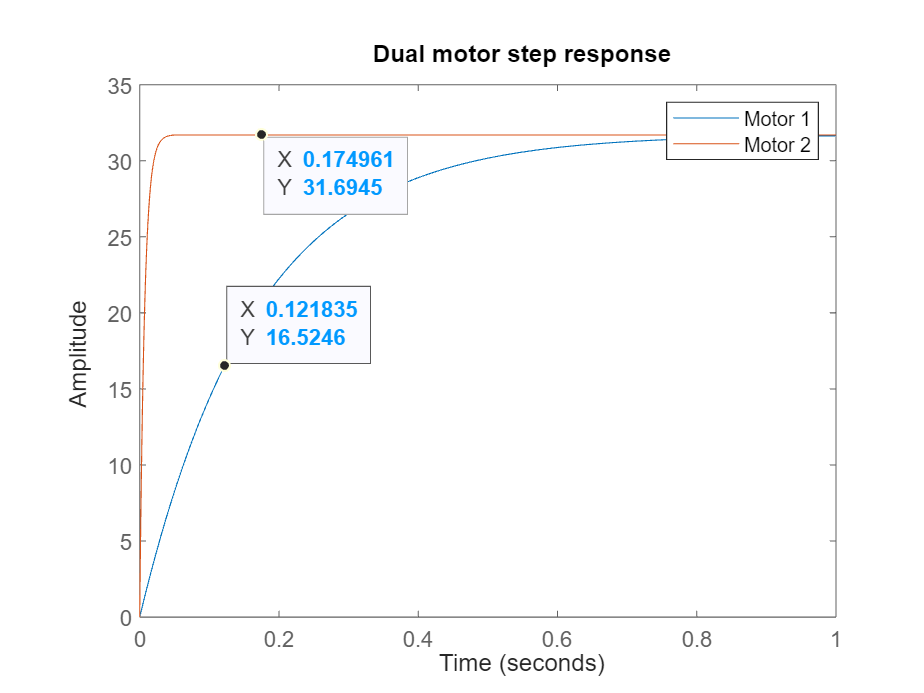

figure;
hold on;
step(s*m1*V);
step(s*m2*V);
title("Dual motor step response");
legend("Motor 1", "Motor 2");
hold off;

- Which motor is faster?

- Does that make sense? Why?

function model = motorModel(I, k, B)
    a1 = I/k;
    a2 = B/k;
    model = tf(1, [a1, a2, 0]);
end